# Enzyme kinetics within our GRASP: A computational platform for building kinetic models of cellular metabolism

**Marta R. A. Matos, Pedro A. Saa, Nicholas Cowie, Svetlana Volkova, Marina de Leeuw, Lars K. Nielsen**

The aim of this tutorial is to illustrate the execution and use of GRASP for building and analyzing kinetic models of metabolism. This tutorial demonstrates how to build an ensemble of models consistent with experimental data. A simple model of the adenine nucleotide cycle (Valero et al. 2006) is employed for illustrative purposes. This model contains 3 reactions, 3 balanced metabolites and 6 external metabolites (not balanced). Also, this model has 1 moeity conservation relation.

### 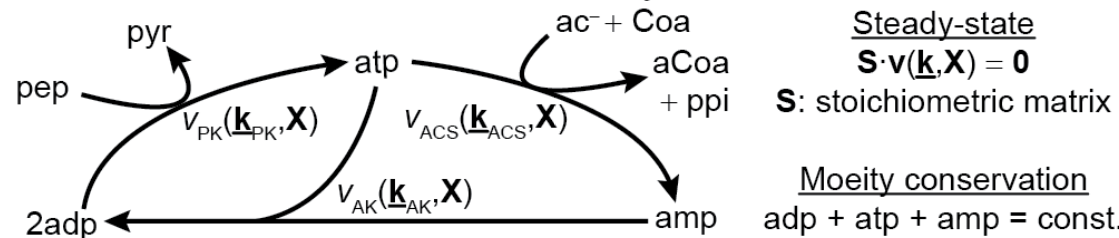

**Figure 1.** Illustrative scheme of the adenine nucleotide cycle.

## Tutorial 02: Building an ensemble of models consistent with experimental data (rejection mode)

Clear all variables and add functions to path.  Note that you need to be in the tutorials folder.

clear, close all
rng('default');                 % for reproducibility
addpath(fullfile('..', 'matlab_code', 'analysisFxns'), ...
        fullfile('..', 'matlab_code', 'ensembleFxns'), ...
        fullfile('..', 'matlab_code', 'patternFxns'));

Set the maximum number of models to sample. This is particularly important when simulating the model from the prior (i.e., no experimental data defined)

maxNumberOfSamples = 1e5;

Set a threshold for the minimum Jacobian eigenvalue of the system. Models with values below this threshold will be discarded due to unstability criteria.

eigThreshold = 1e-5;

Define the model ID name, input and output files. These paths are necessary for executing GRASP.

modelID = 'tutorial_02_adenine_cycle';
inputFile  = fullfile('..', 'io', 'input', modelID);
outputFile = fullfile('..', 'io', 'output', [modelID, '.mat']);

Build the kinetic ensemble. In this case, we will build an ensemble of 12 models. These models will have a max. flux discrepancy of 30% (0.3 in the specification sheet) for all the experimental conditions. Here, the experimental data corresponds to flux and metabolite pool data for five different conditions. It is important to note that, as in the case of single metabolite and enzyme concentration data, pool data must be normalized using the reference state data. The metabolite pool data is given by:

adp_i + adp_i + adp_i = totalPool_i, where i = {1,...,5} represent exp. conditions (all these concentrations are normalized by the reference state concentrations)

To accelerate the execution of the sampler, we will use the parallel mode with 4 cores assigned.

tic
ensemble = buildEnsemble(inputFile, outputFile, maxNumberOfSamples, eigThreshold);

Error using xlsread (line 136)
XLSREAD unable to open file '..\io\input\tutorial_02_adenine_cycle.xlsx'.
File 'C:\Users\Juan Pablo Schnettle\Documents\GitHub\GRASP\io\input\..\io\input\tutorial_02_adenine_cycle.xlsx' not found.

Error in loadEnsembleStructure (line 97)
[xData,strData]     = xlsread(xlsxFile,'general');                      % load general

toc

Using this ensemble, we compute flux and metabolite control coefficients and visualize the final results for all the conditions (reference + five experimental conditions)

mcaResults = controlAnalysis(ensemble,1);
categories = {};         % Displays MCA results for all the reactions
plotControlAnalysis(mcaResults, ensemble, categories);

## References

- Valero E, Varón R, García-Carmona F. (2006) A kinetic study of a ternary cycle between adenine nucleotides. The FEBS Journal **273**: 3598–3613